# Script for testing

This script allows for testing the functions to be implemented for lab no 6.

In order to test each function, we need to create the Workspace in which the functions will run. Thus, we set the global variables. The common values among all the tests are set in the first section. Then, we have one section per experiment. We set in the section the values needed by that function.

**What shall I do with this code?**

You have to implement several functions. Then you use this script to **test** them, by varying the free parameters and observing the result.

## Common parameters

Always run this section at the beginning

clc; clear variables; 
% Parameters
global params img decodedFrameBuffer
params.quantizationSteps = 20; % Start with a single value, then use a vector for multiple encodings
params.inputVideoName = 'foreman'; % Use one of the provided .y files
params.inputVideoFile   = [params.inputVideoName '_cif.y'];  % full input file name. Add the path if needed
params.modeSelectionLabmda = 10;  % Lagrangian param for mode selection. Start with 10
params.motionEstimationLambda = 3; % Lagrangian param for ME. Start with 3
params.ME.search=5;  % ME search window size
params.ME.dist = 'SAD'; % ME metric
params.GOPSize = 1; % Start with an "All Intra" configuration. Then move to IPP..P  Gops
params.blockSize = 8;  % Can be modified later
params.nRow = 288;
params.nCol = 352;
params.verbose = 1;  % Setting the verboseness level might be useful for debugging and testing
% other possible parameters can be set as fields of the struct
decodedFrameBuffer.reference = zeros(params.nRow,params.nCol); % Since we do not use B, one decoded refernce is enough
decodedFrameBuffer.current   = zeros(params.nRow,params.nCol); % We also need a buffer for the current encoded image

 

## Test 1: `loadIntra`

Complete the implementation of `loadIntra.m`

Then, run the following. You should be able to load the first image of the selected GOP

You can also modify the gop size in the `params` variable

gopIndex = 8; %% Modify this value and test the result
params.firstFrameGOP = params.GOPSize * (gopIndex-1) +1 ;
x = loadIntra(gopIndex);

Loading Intra image from GOP 008 (image no 008 in the file)


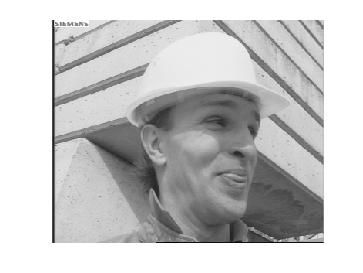

figure; image(uint8(x)); axis image; axis off; colormap("gray")

## Test 2: ypsnr

Complete the implementation of `ypsnr` 

Then test it here. Remember that if you increase the standard deviation (STD) of the noise of a factor 2, the MSE will increase of 4 (because it is the **squared** error) and then the PSNR will decrease of about 6 dB.

Since $\textrm{MSE}\approx {\textrm{noiseSTD}}^2$ find the theoretical value of PSNR and compare with the empiric value.  

gopIndex = 11;
params.firstFrameGOP = params.GOPSize * (gopIndex-1) +1 ;
x = loadIntra(gopIndex);

Loading Intra image from GOP 011 (image no 011 in the file)


noiseSTD = 49;  %% TEST if the noise standard deviation is doubled, the PSNR should decrease of 6 dBs
                 % Modify this value and test the function  
y = x+noiseSTD*randn(size(x));
fprintf('STD: %3.2f, PSNR: %5.3f dB\n',noiseSTD,ypsnr(x,y))

STD: 49.00, PSNR: 14.352 dB


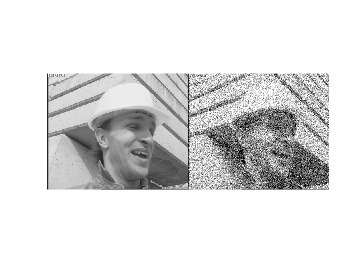

figure; image(uint8([x y])); axis image; axis off; colormap("gray")

MSE = noiseSTD^2; 
theoreticalPSNR = 10*log10(255*255/MSE)

theoreticalPSNR = 14.3269

empiricPSNR = ypsnr(x,y)

empiricPSNR = 14.3515

## Test 3: appendToFile(imgBitStream)

Complete the provided `appendToFile`

In the test environment, we create the workspace needed by this function, and in particular we create the output file and the file identifier to write on it.

We also create a random bitstream, made up of zeros and ones. This is done at line 42. We first create a random sequence of numbers between 0 and 1. Then we compare with the threshold 0.5. Finally we add 48, obtaining a vectors of random 48 and 49. Finally we convert to char, since the ASCII code of zero [one] is 48 [49]. 

% Let us create an output file
testFileName = 'test_appendFile.bin';
params.fid = fopen(testFileName, 'wb');
% Let us create a random bitstream, and append it to the file
nBytes = 3;        % Modify this value and test the function  
nBits = 8*nBytes;
bitStream = char(double(rand(1,nBits)>0.5)+48); % char(48) is '0'
appendToFile(bitStream);
fclose (params.fid);

% Let us check the size of the file
sz = dir(testFileName).bytes;
fprintf('Stream size: %d bytes\nFile size:   %d bytes\n',nBytes, sz);

Stream size: 3 bytes
File size:   3 bytes



% Let us check the content of the file
fid = fopen(testFileName, 'rb');
fromFile = fread(fid,nBits, 'ubit1')+48;
fclose(fid);
fprintf('Written: %s\nRead:    %s\n',bitStream,fromFile);

Written: 010011000000100110100011
Read:    010011000000100110100011


## Test 4: intraBlockCoder

Here you have to complete the intraBlockCoder function.

It perform the JPEG-like encoding of a single block. 

We need to define the quantization matrix. This is done here:

q_mtx1 =     [16 11 10 16 24 40 51 61; 
            12 12 14 19 26 58 60 55;
            14 13 16 24 40 57 69 56; 
            14 17 22 29 51 87 80 62;
            18 22 37 56 68 109 103 77;
            24 35 55 64 81 104 113 92;
            49 64 78 87 103 121 120 101;
            72 92 95 98 112 100 103 99];
params.qual = 80; 
SF = (params.qual==100)+(params.qual<=99&&params.qual>50)*(200-2*params.qual)+ (params.qual<=50)*(5000/params.qual);
params.q_mtx = ceil(q_mtx1*SF/100);
params.q_mtx (params.q_mtx>256)=256; 


Let us encode the same block as in Lab 4. We must obtain the same results. We take the block in the image "color_small" at positions 

When we run the script for lab 4 with this block, we should obtain the same results as here. We have copied here the values of the previous DC coeff and of the block:

previousDC = -80;
grayBlock =[
   60.9052   63.2249   67.2717   70.1239   72.4435   74.0633   77.8533   81.2886
   60.0464   60.9052   64.0837   66.4129   67.2717   68.3873   70.9638   73.2835
   56.9048   58.8604   59.9665   61.0358   60.5411   61.0547   61.4652   59.7570
   51.6815   53.5769   52.7275   49.4322   48.5639   53.3527   67.6951   85.7811
   40.6568   40.8852   51.4195   74.1028   94.0137  108.0959  118.1072  130.3832
   72.8188  100.1277  114.4237  120.9576  126.9651  127.4409  125.9285  129.7520
  117.9741  119.5749  120.3264  122.3618  125.1581  127.1935  130.2467  132.2821
  116.4840  120.0507  122.3523  124.1404  125.4149  127.7071  131.5211  132.5389 ];

Now we can run the test:

centeredValues = grayBlock-128;
[bits, decCenteredValues] =blockIntraCoding(centeredValues,previousDC)

Unrecognized field name "q_mtx_Intra".

Error in blockIntraCoding (line 4)
quantizedDctBlock = round(dctBlock./params.q_mtx_Intra);

bpp = numel(bits)/64
decodedBlock = decCenteredValues+128; 

Compare to the results obtained in lab no 4.

## Test no 5. Complete Intra coding function

Here we test the full Intra coding function Let us set all the parameters and encode an image in Intra mode

gopIndex = 1; %% Modify this value and test the result
params.firstFrameGOP = params.GOPSize * (gopIndex-1) +1 ;
img = loadIntra(gopIndex);
imgBitStream = IntraImgEncoder();
imgBPP = numel(imgBitStream)/numel(img);
PSNR = ypsnr(img,decodedFrameBuffer.current);
fprintf('RATE: %4.3f bpp\nPSNR: %4.2f dB\n',imgBPP,PSNR)


 Example of typical values, first image of foreman:

Quality = 80 - rate = 1.181 bpp - PSNR = 38.61 dB